clear
clc
close
Convolution_code(randsrc(1, 100, [0 1]))%%

ans =      0     0     1     1     1     0     0     0     0     1     1     1     1     0     0     1     1     0     1     1     1     1     0     0     1     0     0     1     0     0     1     1     1     0     1     0     1     1     0     1     1     0     0     1     0     1     0     1     1     1


10*log10(50/8)

ans = 7.9588

clc
clear
close
core = zeros(1, 2);
ber = zeros(20, 1);
db = zeros(20, 1);
k = 1

k = 1

for Esav = 10 : 30 : 610
    for i = 1: 1000
        m = [0 0 0 0];
        a = Sixteen_QAM(m, Esav);
        b = AWGN_channel(a, 2);
        c = ML_demodulation(b, Esav);
        core = core + BER_analysis(m, c);
    end
    ber(k) = core(2)/(core(1)+core(2));
    db(k) = 10*log10(Esav/4/8);
    k = k + 1;   
end
ebofNodb=-2:0.001:14

ebofNodb =    -2.0000   -1.9990   -1.9980   -1.9970   -1.9960   -1.9950   -1.9940   -1.9930   -1.9920   -1.9910   -1.9900   -1.9890   -1.9880   -1.9870   -1.9860   -1.9850   -1.9840   -1.9830   -1.9820   -1.9810   -1.9800   -1.9790   -1.9780   -1.9770   -1.9760   -1.9750   -1.9740   -1.9730   -1.9720   -1.9710   -1.9700   -1.9690   -1.9680   -1.9670   -1.9660   -1.9650   -1.9640   -1.9630   -1.9620   -1.9610   -1.9600   -1.9590   -1.9580   -1.9570   -1.9560   -1.9550   -1.9540   -1.9530   -1.9520   -1.9510


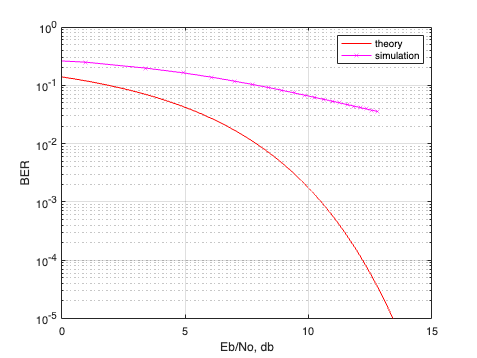

figure(1), semilogy(ebofNodb, 1*(3/4)*qfunc(sqrt((3*4/15)*10.^(ebofNodb/10))), 'rs-', LineWidth=0.01);
hold on
axis([0 15 10^-5 1])
grid on
semilogy(db, ber, 'mx-')
legend('theory', 'simulation')
xlabel('Eb/No, db')
ylabel('BER')

clc
clear
close
core = zeros(1, 2);
Esav = 320;
ber = zeros(10, 1);
db = zeros(10, 1);
k = 1;
for i = 1: 1000
    m = [0 0 0 0];
    a = Sixteen_QAM(m, Esav);
    b = AWGN_channel(a, 2);
    c = ML_demodulation(b, Esav);
    core = core + BER_analysis(m, c);
end
ber = core(2)/(core(1)+core(2))
db = 10*log10(Esav/4/8)
